%path = [0,0;0,-5;5,0];
path = [0,0;5,0;5,5;10,5];
%path = [0,0;1,0.2;1.8,0.6;2.6,1.0;3.2,2];
%interp1((1:N),path[:1])


N = 30;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
%x0 = [zeros(7*N,1); 1];
x0 = [1*ones(N,1);1*ones(N,1);0.5*ones(N,1);0.5*ones(N,1);1*ones(N,1);0*ones(N,1);0*ones(N,1);1];
costfcn = @(x) x(end);
%options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter')
%xstar = fmincon(@(x)costfcn_dist(x,path), x0,[],[],[],[],[],[], @(x)nonlcon_path(x,path), options)

options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'SpecifyObjectiveGradient', false, 'SpecifyConstraintGradient', true);
xstar = fmincon(@(x)costfcn_dist(x,path), x0, [], [], [], [], [], [], @(x)nonlcon_w_grad(x,path), options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% xstar = it_nonlcon(costfcn, x0, options);

% Extract states from design vectorgit 
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);
disp(x);

    0.0000
    0.0000
    0.0081
    0.0046
    0.0000
    0.0007
    0.0010
    0.0022
    0.0022
    0.0065
    0.0256
    0.0773
    0.1907
    0.3775
    0.6538
    1.0297
    1.5123
    2.1181
    2.8336
    3.5578
    4.2802
    4.9720
    5.0323
    4.9125
    5.1389
    6.2678
    7.7033
    8.8540
    9.6177
   10.0000



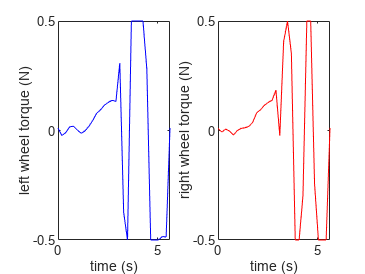


% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

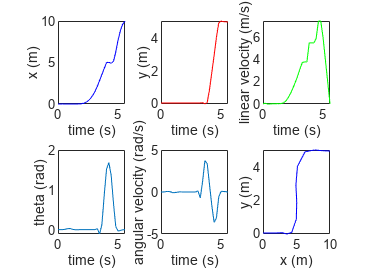


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

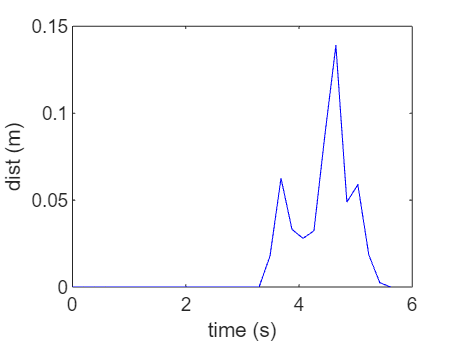

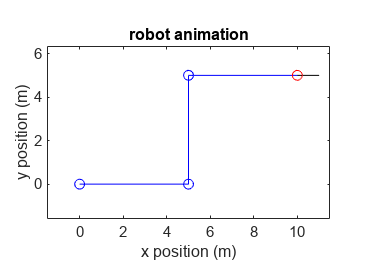


figure
dists = zeros(N,1);
for i = 1:N
    dists(i) = minDistance([x(i),y(i)], path);
end
plot(ts, dists, 'b-')
xlabel("time (s)")
ylabel("dist (m)")

animate_direct_collocation(xstar, path)

% use symbolic toolbox to get cost and constraint function gradients
syms x [7*N+1 1]
% matlabFunction(gradient(costfcn(x), x), "File", "costfcn_gradient.m");

[C, Ceq] = nonlcon_path(x,path);
matlabFunction(jacobian(C, x), "File", "nonlcon_c_jacobian.m", "Vars", {x});
matlabFunction(jacobian(Ceq, x), "File", "nonlcon_ceq_jacobian.m", "Vars", {x});

function [f, gradf] = costfcn_w_grad(x)
    f = x(end);
    gradf = costfcn_gradient();
end

function [C, Ceq, GC, GCeq] = nonlcon_w_grad(x,path)
    [C, Ceq] = nonlcon_path(x, path);
    GC = nonlcon_c_jacobian(x)';
    GCeq = nonlcon_ceq_jacobian(x)';
end

function cost = costfcn_dist(d,path)
    N = ((numel(d)-1)/7);
    x = d(2*N+1:3*N);
    y = d(3*N+1:4*N);
    dists = zeros(N,1);
    for i = 1:N
        dists(i) = minDistance([x(i),y(i)], path);
    end
    cost = sum(dists.^2) + 0.1*d(end);
end